# Paper3: fig 1D

## Setting up WS

CurrentFolder = pwd

CurrentFolder = '/Users/zhuochengxiao/Library/CloudStorage/OneDrive-Personal/Documents/GitHub/NYU-Vision-2Drive'

addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
SaveToFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper3PlotingData/']; % V1D2
DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/25Function_Binocular/']; % V1D2
DataFolder1 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/16Function_Scheme/LARGE16/']; % V1D2
DataFolder2 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/25Function_binocular_realLGN/']; % V1D2
DataFolder4 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper2PlotingData/Typical_trajs/']; % V1D2
addpath([CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'])

addpath(DataFolder4)
addpath(SaveToFolder)
addpath(DataFolder2)
addpath(DataFolder1)
addpath(DataFolder)
addpath([CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'])

### B1. Load LDE computations and do Fr distributions

Should rerun Sect 1 after in case loaded file contain any paths.

DataPt = 'V4D2'; %'V4D1'; 'V5D1'
load(sprintf("AllMFPixPara_Paper2TuneFig1%s.mat",DataPt))

CurrentFolder = pwd;
FigurePaperPath = [CurrentFolder '/Paper3Fig/']; % V1D2
close all

Renormalize the connectivities

N_HCOutX = 4; N_HCOutY = 4; PixNumOut = N_HCOutX*N_HCOutY*NPixX*NPixY;
NPixX = 10; NPixY = 10;

C_SS_mean = sparse(AveSpatKer_Rec(C_SS_Pixel_Us,N_HC,...
    N_HCOutX,N_HCOutY,NPixX,NPixY));
C_CS_mean = sparse(AveSpatKer_Rec(C_CS_Pixel_Us,N_HC,...
    N_HCOutX,N_HCOutY,NPixX,NPixY));
C_IS_mean = sparse(AveSpatKer_Rec(C_IS_Pixel_Us,N_HC,...
    N_HCOutX,N_HCOutY,NPixX,NPixY));
C_SC_mean = sparse(AveSpatKer_Rec(C_SC_Pixel_Us,N_HC,...
    N_HCOutX,N_HCOutY,NPixX,NPixY));
C_CC_mean = sparse(AveSpatKer_Rec(C_CC_Pixel_Us,N_HC,...
    N_HCOutX,N_HCOutY,NPixX,NPixY));
C_IC_mean = sparse(AveSpatKer_Rec(C_IC_Pixel_Us,N_HC,...
    N_HCOutX,N_HCOutY,NPixX,NPixY));
C_SI_mean = sparse(AveSpatKer_Rec(C_SI_Pixel_Us,N_HC,...
    N_HCOutX,N_HCOutY,NPixX,NPixY));
C_CI_mean = sparse(AveSpatKer_Rec(C_CI_Pixel_Us,N_HC,...
    N_HCOutX,N_HCOutY,NPixX,NPixY));
C_II_mean = sparse(AveSpatKer_Rec(C_II_Pixel_Us,N_HC,...
    N_HCOutX,N_HCOutY,NPixX,NPixY));

Select the target pixel and present pre syn pixs

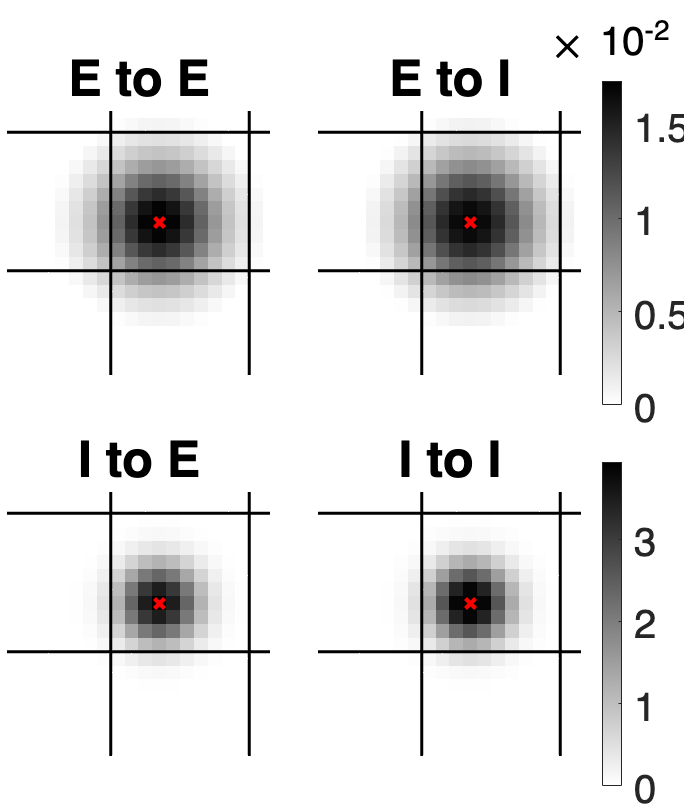

close all

PId = 534;
C_IE = C_IS_mean+C_IC_mean;
C_SE = C_SS_mean+C_SC_mean;
C_CE = C_CS_mean+C_CC_mean;
C_II = C_II_mean;
C_EI = C_SI_mean*(1-CplxR) + C_CI_mean*CplxR;
C_EE = C_SE * (1-CplxR) + C_CE * CplxR;

fig1 = figure("Name",sprintf('Fig1D_PreSyn'),...
    'units','normalized','outerposition',[0,0,0.3,0.55]);
ha = tight_subplot(2,2,[.07 .07],[.03 .1],[.01 .15]);

c = gray;
c = flipud(c);
cmap = colormap(c);
cmap(1,:) = [1 1 1];

axes(ha(1));
Perc_EE = C_EE(PId,:)'/sum(C_EE(PId,:),'all')*100;
ShowField(Perc_EE,1:1600,40,40)
hold on
scatter([14],[14],50,'r','Marker','x',"LineWidth",2)
title('E to E','FontSize',25)
clim([0 max(Perc_EE,[],'all')])
colorbar off

axes(ha(2));
Perc_IE = C_IE(PId,:)'/sum(C_IE(PId,:),'all')*100;
ShowField(Perc_IE,1:1600,40,40)
hold on
scatter([14],[14],50,'r','Marker','x',"LineWidth",2)
title('E to I','FontSize',25)
clim([0 max(Perc_IE,[],'all')])
Pos1 = get(gca,'Position');
cbr1 = colorbar(gca, 'Position', [Pos1(1)+Pos1(3)+0.03  Pos1(2)  0.03  Pos1(4)]);
cbr1.Title.String = '\times 10^{-2}';
set(cbr1,'FontSize',20)

axes(ha(3));
Perc_EI = C_EI(PId,:)'/sum(C_EI(PId,:),'all')*100;
ShowField(Perc_EI,1:1600,40,40)
hold on
scatter([14],[14],50,'r','Marker','x',"LineWidth",2)
title('I to E','FontSize',25)
clim([0 max(Perc_EI,[],'all')])
colorbar off


axes(ha(4));
Perc_II = C_II(PId,:)'/sum(C_II(PId,:),'all')*100;
ShowField(Perc_II,1:1600,40,40)
hold on
scatter([14],[14],50,'r','Marker','x',"LineWidth",2)
title('I to I','FontSize',25)
clim([0 max(Perc_II,[],'all')])
colorbar off
Pos2 = get(gca,'Position');
cbr2 = colorbar(gca, 'Position', [Pos2(1)+Pos2(3)+0.03  Pos2(2)  0.03  Pos2(4)]);
set(cbr2,'FontSize',20)

for axId = 1:4
axes(ha(axId));
axis off
box off
colormap(cmap)
axis([3 22 3 22])
end

FigName1 = sprintf('Fig1D-presyn');
savefig(fig1,[FigurePaperPath FigName1 '.fig']);

fig1.PaperUnits = 'centimeters';
fig1.PaperSize = [14,14];
fig1.PaperOrientation = "landscape";
exportgraphics(fig1,[FigurePaperPath FigName1 '.pdf'],'Resolution',150)
close all